## **River profile analysis & hypsometry**

clc
clear 
close all
DEM = GRIDobj('Harz_utm.tif');  % load DEM

The hypsometric integral (HI) is often used to estimate the incision of an uplifted surface. Well incised regions display low HI, because most of the landscape lies at lower elevations, and regions with barely incised low relief surfaces should have a high HI (see plot below). Let's calculate HI and see how well it does at outlining the low relief surfaces in the Harz. The equation for HI is shown below. You can use the 'localtopography' function to calculate all components of the equation. Play around with the radius to see what works best.

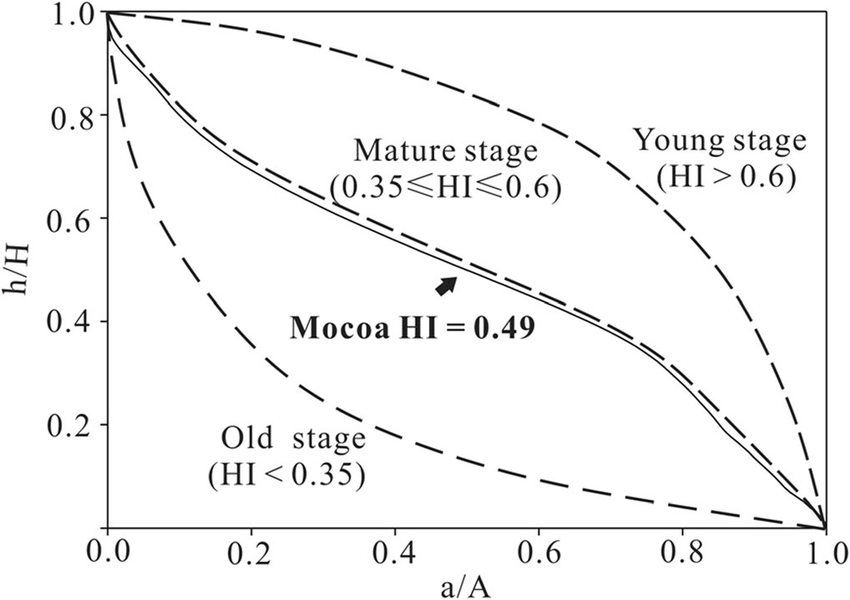


radius = 2000;
hmean
hmin   
hmax   

HI 


Before you start plotting. Have a look at the scientific color maps integrated within TT [LINK](https://topotoolbox.wordpress.com/2018/08/13/overview-of-scientific-colormaps/). HI ranges from 0 to 1, therefore a diverging colormap like 'vik' should work well. You can call the scientific color maps with the ttscm command as shown below.

imageschs(DEM,HI,'colormap',ttscm('vik'))

Apparently, the HI is not the best metric to outline the low-relief surfaces here. Let's try roughness. TT has many different metrics to calculate roughness. Stick ot the ruggedness index and vary the kernel size until you are happy with the outcome and can identify the areas of low relief.

kernelSize = 21
rough  % compute the roughness with the kernel size from above
figure()
% plot the surface rooughness with the hillshade basemap, and with the
% "vik" color map

Let's calculate the stream network. Use a minimum drainage area of 2 km² and carve the flow directions. 

FD  % flow direction
% flow accumulation
% delineate stream network

A common way of loooking at river networks is to investigate their longitudinal profiles. 

Smod = klargestconncomps(S);  % selects the longest connected stream network in the study region

h = figure();
set(h,'Units','normalized','Position',[0 0 1 .5]); 
subplot(1,2,1)
% plot your DEM
hold on
% plot the stream nework on top of the DEM as black lines 
subplot(1,2,2)
% use the plotdz function to plot the river profile

As you can see, the profiles are pretty wiggly due to DEM errors. This means we should smooth our river profile elevations. Smoothing is an art in itself, and TT provides several ways of doing this. For now, let's use the smooth function and you can play around with the smoothing factor K to see what value seems reasonable. 

K = 20
Z % apply smooth function with smoothing factor K
h = figure();
set(h,'Units','normalized','Position',[0 0 1 .5]); 
subplot(1,2,1)
% plot DEM
hold on
% plot stream on top of DEM
subplot(1,2,2)
% plot elevation profile of stream

Better than smooth is the crs (constrained regularized smoothing), which is the most sophistacted (but also slowest) smoothing function for TT. Run crs, plot the results and try to identify the main difference between crs and the other smoothing algorithm. Besides, the smoothing factor K, crs requires a second input tau. Here's the [link](https://topotoolbox.wordpress.com/2017/08/14/smooth-operator/) to a TT blog post that visaulizes the crs smoothing. Think about errors in DEMs. Can you make an educated guess if you should pick a tau >, <, or = 0.5? crs is pretty computationally heavy and will probably get your computer fan going ;)

Zcrs
% plot the crs smoothed river profile

There is also the 'crsapp'. You can try it out. It will will let you interavtively, change the K and tau parameters and visualize the change in the river profile.

The smaller the drainage area of a river, the steeper its channel. This relationship is often referred to as Flint's law:


$$S=k_s *A^{-\Theta }$$


where channel slope S scales with drainage area, to the power of the so-called concavity. $k_s$ is the river steepness normalized for drainage area. To compare the river steepness $k_s$ between streams, we need to hold the concavity constant. Luckily for us, concavity usually doesn't change so much on our planet, and is commonly around 0.45 to 0.5. Using the same concavity between streams is called a reference concavity and the channel steepness with a reference concavity is the normalized channel steepness Ksn. 

theta_ref = 0.45;

Optional: You can esimtate the best fit concavity in TT with the mnoptim function. However, in our study region this does not work so well. Try out the mnoptim function and try to understand why the output of concavity values for the entire DEM is very different from the standard 0.45 value.

% run mnoptim

So lets calculate ksn. Calculate Ksn with the reference concavity and the smooth parameter from before.

Ksn % calculate Ksn

Just as a side note. TT now also comprises the function 'loessksn' that uses a locally weighted scatterplot smoothing to calculate ksn. If you're like me and don't exactly now that a LOESS regresison is, watch this nice [explanation video](https://www.youtube.com/watch?v=Vf7oJ6z2LCc).

Now, let's make a nice ksn map. Plot the DEM using a black and white gradient and plot ksn on top.

h = figure();
set(h,'Units','normalized','Position',[0 0 1 1]); 
% plot gray scale DEM
% plot Ksn with plotc function
colorbar
caxis([0,80]) % this improves visibility to make sure the Ksn values are not adjusted to a single high outlier

Ksn is (under uniform climatic, and lithologic conditions) used to infer variations in uplift rate in space and time. Try to interpret the Ksn map in terms of differences in rock type and uplift rate through time. We'll get back to this later with the stream profiles. 

Another standard metric often computed for drainage network is $\chi =\int_{\textrm{x0}}^x {\left(\frac{A_0 }{A}\right)}^{\frac{m}{n}} \textrm{dx}\;\ldotp \;$$\chi$ is used as an indicator of drainage network stability and divide migration. Follow this [link](https://www.researchgate.net/publication/260611497_Dynamic_Reorganization_of_River_Basins/figures?lo=1) and look at figure 1 to understand what chi is all about and how it is used to predict the motion of drainage divides. Let's see if the drainages in the Harz are/seem in equilibrium.  The calculation of chi has to start at a common base level. Also, the calculation of the metric relies on uniform rock type and uplift conditions. Which parts of the map make sense to exclude when you consider rock type and/or differences in uplift rate? Play around with the button to determine your preferred base level. 

baseLevel = 200
DEMb = DEM > baseLevel;
imageschs(DEM,DEMb)

Cool! You've selected a base level. Chi is calculated only along the streams, therefore, you need to clip your stream network to the area upstream of your base level. Use the function griddedcontour to make a contour and  'modfiy' to clip your STREAMobj. Once, you've clipped your stream network you can use 'chitransform' to calculate chi with your concavity from before.

Con  % define a contour
Schi % clip your stream network 
chi  % calculate chi

Now, let's plot the chi map to look at potential disequilibrium in the drainage network and potential divide movement. We'll use the roma color map. I suggest you plot the DEM with the "gray" colorbar and then plot the chi values on top with the 'plotc' command. Try it out!

cc = flipud(ttscm('roma'));  % load roma color map and reverse it to look better
h = figure();
set(h,'Units','normalized','Position',[0 0 1 1]); 
% plot DEM
% plot chi, use thick line width, e.g. 2
% set colormap
% % add colorbar

Rivers with low chi values that are next to rivers with high chi values are supposed to eat away drainage area from the high chi basins over time. Can you find such disequilibrium in the drainage network of the Harz?

Most of the chi maps are plotted similarly to what we've just done. But personally, I find it sometimes hard to really see the disequlibrium. Chi can only be calculated for streams but there's a trick I like to use for better visibility. I project values from the streams onto the hillslopes by simply reversing the flow routing. This means that a hilllslope pixel simply gets assigned the value of the stream pixel that water  from this hillslope pixel would flow into. In TT values that are only stored for stream nodes are referred to as nal (node attribute list). Our chi values are a "nal" but can be projected onto the hillslopes with  'mapfromnal'. Use it to make a chi map!

chiMap % project chi values onto hillslope
D % let's also calculate the divides and plot them on the map to better outline where basin boundaries lie
D % calculate the order of the divide to make it look prettier ;)
h = figure(); 
set(h,'Units','normalized','Position',[0 0 1 1]); 
imageschs(DEM,chiMap,'colormap',cc(1:255,:),'colorbar',true)
hold on
% plot divides in black and use a plotting limit to remove the tiny divides

Now, this looks much clearer and easier to interpret. You see the main divides and you should be able to pick out where the divide is supposed to move in the future.

The main divide seems to be moving north as rivers from the south eat into the low-relief surface in the central Harz. However, keep in mind that this interpretation builds on the uniform rock type and uplift assumption. Another explanation would be that the uplift rates in the south are higher and the divide locatoin is close to equlibrium. 

## River profiles

Often we want to look at an elevation (or some other metric) profile of a river along its course. Let's try and do that next. Use the interactive function below to pick a drainage basin you want to investigate. Click on the drainage basin and export the stream network by giving it a name (remember the name!). Close the window and move on.

extractconncomps(Schi); % let's extraxt the same stream that we had before with the largest connected component

you can use the plotdz function to examine the chi-elevation plot of a stream. Try plotting your data with 'chiplot'. What do you see? Are there knickpoints (clear brakes in river slope)?

figure()
% use chiplot function

Let's make a nice plot for your selected stream showing the stream in map view colored by Ksn, in a second plot show the elevation profile of the stream also colored by Ksn, and in a thrid plot the chi-elevation data (also colored by Ksn). First, calculate Ksn for your selected stream and don't forgot to add some smoothing to the Ksn function. Use the 'colormethod' option to color your stream in the second panel by ksn and depending on your Ksn values play around with the limits on the colorbar.

% ksn just for stream
Ksn_stream % calculate Ksn

h = figure();
set(h,'Units','normalized','Position',[0 0 1 1]); 
subplot(2,2,1:2)
% plot DEM and selected stream
subplot(2,2,3)
% plot stream elevation profile with Ks coloring
caxis([0,100])
subplot(2,2,4)
chi_stream  % calculate chi along stream with chitransform
% plot chi profile with Ksn color, also add a label to the colorbar
caxis([0,100])

This is the end! In this lecture you learned how to calculate metrics on the stream network, extract stream elevation, and do some advanced geomorphic analysis like chi-plots of streams. These are your basics when going to a new region and doing, e.g., tectonic geomorphology. I hpe you enjoyed this script!